% Author - Sudhanva Gokhale (SUD)
% Central Design and Documentation Team
clear all
clc

%%- LLC Converter Design
 % these are the requirements that we want in our LLC converter
Vin = 375;
Vin_low = 360;
Vin_high = 395;

P_op = 320;
I_op = 20;
V_op = 16;

eff = 95;      % in percentage!!
f_sw = 135e3;  % range -> 70 to 150kHz

%%- Step 1
Mg_step1 = 1;
n = Mg_step1*(Vin/(2*V_op));
n= floor(n)

n = 11



%%- Step 2
V_loss = (P_op*(100-eff))/(eff*I_op)

V_loss = 0.8421


Mg_min = vpa((2*n*((16*0.99)+0.7))/(385),6)

$$Mg\_min = 0.945143$$

Mg_max = vpa(( 11*((16*1.01)+0.7+0.8421) )/ (182.5),6);

 % if overload current capacity = 110% then Mg_max becomes
Mg_max = 1.1*Mg_max

$$Mg\_max = 1.1736734794520543800899758934975$$



%%- Step 3
 % we have to construct Gain vs Normalized freq plot
 % Procedure
 % Take Ln = 1
 % Take Qe = 0.1
 % sweep fsw from 0.1*fo to 10*fo , where fo is resonant freq
 % change Qe from 0.2 to 10
 % change Ln form 5 to 20

fo=135e3;

Ln = 5;

Qe1=0.1;
abs_Mg1 = [];
plot_fsw1 = ((0.1*fo)):100:((10*fo));
for fsw = 0.1*fo:100:10*fo
    Mg1 = (Ln*(fsw/fo)^2)/( ( (Ln+1)*(fsw/fo)^2 -1 ) + i*( ((fsw/fo)^2-1)*(fsw/fo)*Qe1*Ln) );
    abs_Mg1(end+1) = abs(Mg1);
end

Qe2=0.2;
abs_Mg2 = [];
plot_fsw2 = ((0.1*fo)):100:((10*fo));
for fsw = 0.1*fo:100:10*fo
    Mg2 = (Ln*(fsw/fo)^2)/( ( (Ln+1)*(fsw/fo)^2 -1 ) + i*( ((fsw/fo)^2-1)*(fsw/fo)*Qe2*Ln) );
    abs_Mg2(end+1) = abs(Mg2);
end

Qe3=0.5;
abs_Mg3 = [];
plot_fsw3 = ((0.1*fo)):100:((10*fo));
for fsw = 0.1*fo:100:10*fo
    Mg3 = (Ln*(fsw/fo)^2)/( ( (Ln+1)*(fsw/fo)^2 -1 ) + i*( ((fsw/fo)^2-1)*(fsw/fo)*Qe3*Ln) );
    abs_Mg3(end+1) = abs(Mg3);
end

Qe4=0.8;
abs_Mg4 = [];
plot_fsw4 = ((0.1*fo)):100:((10*fo));
for fsw = 0.1*fo:100:10*fo
    Mg4 = (Ln*(fsw/fo)^2)/( ( (Ln+1)*(fsw/fo)^2 -1 ) + i*( ((fsw/fo)^2-1)*(fsw/fo)*Qe4*Ln) );
    abs_Mg4(end+1) = abs(Mg4);
end

Qe5=1;
abs_Mg5 = [];
plot_fsw5 = ((0.1*fo)):100:((10*fo));
for fsw = 0.1*fo:100:10*fo
    Mg5 = (Ln*(fsw/fo)^2)/( ( (Ln+1)*(fsw/fo)^2 -1 ) + i*( ((fsw/fo)^2-1)*(fsw/fo)*Qe5*Ln) );
    abs_Mg5(end+1) = abs(Mg5);
end

Qe6=2;
abs_Mg6 = [];
plot_fsw6 = ((0.1*fo)):100:((10*fo));
for fsw = 0.1*fo:100:10*fo
    Mg6 = (Ln*(fsw/fo)^2)/( ( (Ln+1)*(fsw/fo)^2 -1 ) + i*( ((fsw/fo)^2-1)*(fsw/fo)*Qe6*Ln) );
    abs_Mg6(end+1) = abs(Mg6);
end

Qe7=5;
abs_Mg7 = [];
plot_fsw7 = ((0.1*fo)):100:((10*fo));
for fsw = 0.1*fo:100:10*fo
    Mg7 = (Ln*(fsw/fo)^2)/( ( (Ln+1)*(fsw/fo)^2 -1 ) + i*( ((fsw/fo)^2-1)*(fsw/fo)*Qe7*Ln) );
    abs_Mg7(end+1) = abs(Mg7);
end

Qe8=8;
abs_Mg8 = [];
plot_fsw8 = ((0.1*fo)):100:((10*fo));
for fsw = 0.1*fo:100:10*fo
    Mg8 = (Ln*(fsw/fo)^2)/( ( (Ln+1)*(fsw/fo)^2 -1 ) + i*( ((fsw/fo)^2-1)*(fsw/fo)*Qe8*Ln) );
    abs_Mg8(end+1) = abs(Mg8);
end

Qe9=10;
abs_Mg9 = [];
plot_fsw9 = (0.1*fo):100:((10*fo));
for fsw = 0.1*fo:100:10*fo
    Mg9 = (Ln*(fsw/fo)^2)/( ( (Ln+1)*(fsw/fo)^2 -1 ) + i*( ((fsw/fo)^2-1)*(fsw/fo)*Qe9*Ln) );
    abs_Mg9(end+1) = abs(Mg9);
end

% ----

max_mg_1 = max(abs_Mg1)

max_mg_1 = 4.9340

max_mg_2 = max(abs_Mg2)

max_mg_2 = 2.5217

max_mg_3 = max(abs_Mg3)

max_mg_3 = 1.2024

max_mg_4 = max(abs_Mg4)

max_mg_4 = 1.0445

max_mg_5 = max(abs_Mg5)

max_mg_5 = 1.0247

max_mg_6 = max(abs_Mg6)

max_mg_6 = 1.0052

max_mg_7 = max(abs_Mg7)

max_mg_7 = 1.0008

max_mg_8 = max(abs_Mg8)

max_mg_8 = 1.0003

max_mg_9 = max(abs_Mg9)

max_mg_9 = 1.0002

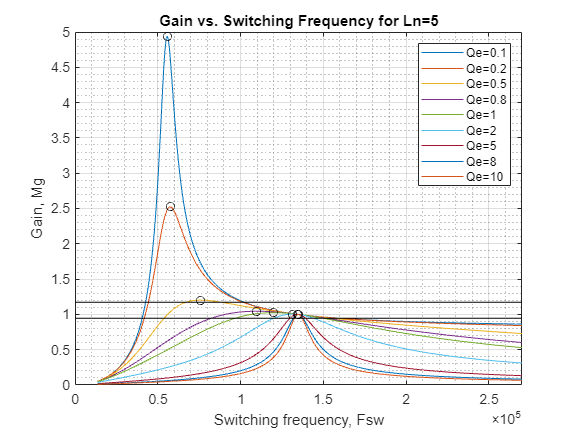

 % We have to look at the Gain vs. Switching Frequency plot and manually
 % write out the frequency for which the gain is maximum for each Qe curve
 % WARNING!! The values below will change when the above paramenters are
 % changed, values will have to be reobserved and re written manually

fc0_1 = 5.57e4;
fc0_2 = 5.75e4;
fc0_3 = 7.57e4;
fc0_4 = 1.0985e5;
fc0_5 = 1.19885e5;
fc0_6 = 1.315e5;
fc0_7 = 1.345e5;
fc0_8 = 1.348e5;
fc0_9 = 1.349e5; 

figure
plot(plot_fsw1,abs_Mg1,plot_fsw2,abs_Mg2,plot_fsw3,abs_Mg3,plot_fsw4,abs_Mg4...
    ,plot_fsw5,abs_Mg5...
    ,plot_fsw6,abs_Mg6,plot_fsw7,abs_Mg7,plot_fsw8,abs_Mg8,plot_fsw9,abs_Mg9)
title('Gain vs. Switching Frequency for Ln=5')
ylabel('Gain, Mg')
xlabel('Switching frequency, Fsw')
xlim([0 (2*fo)])
hold on
line([0,2*fo],[Mg_max,Mg_max],'Color','black')
line([0,2*fo],[Mg_min,Mg_min],'Color','black')
plot(fc0_1,max_mg_1,'o','Color','k')
plot(fc0_2,max_mg_2,'o','Color','k')
plot(fc0_3,max_mg_3,'o','Color','k')
plot(fc0_4,max_mg_4,'o','Color','k')
plot(fc0_5,max_mg_5,'o','Color','k')
plot(fc0_6,max_mg_6,'o','Color','k')
plot(fc0_7,max_mg_7,'o','Color','k')
plot(fc0_8,max_mg_8,'o','Color','k')
plot(fc0_9,max_mg_9,'o','Color','k')
hold off
grid on
grid minor
legend('Qe=0.1','Qe=0.2','Qe=0.5','Qe=0.8','Qe=1','Qe=2','Qe=5','Qe=8','Qe=10')

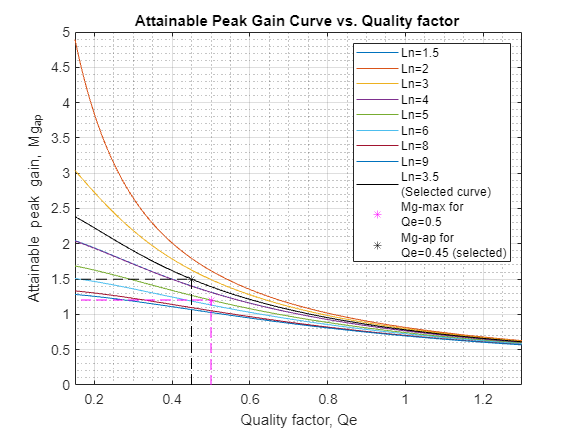


% Now Attainable peak gain vs. Quality factor plot will be constructed
 % Now fsw and Ln will be fixed and we will vary Qe
 % fsw = fsw_1 which is equal to 7.57e4 = fc0_3
fsw_1 = fc0_3;
originally_selected_Qe = 0.5;

Mg_1_abs=[];
Ln_1 = 1.5;
for Qe_n = 0.09:0.001:1.30
    Mg_1 = (Ln_1*(fsw_1/fo)^2)/( ( (Ln_1+1)*(fsw_1/fo)^2 -1 ) ...
        + i*( ((fsw_1/fo)^2-1)*(fsw_1/fo)*Qe_n*Ln_1) );
    Mg_1_abs(end+1) = abs(Mg_1);
end
Mg_2_abs=[];
Ln_2 = 2;
for Qe_n = 0.09:0.001:1.30
    Mg_2 = (Ln_2*(fsw_1/fo)^2)/( ( (Ln_2+1)*(fsw_1/fo)^2 -1 ) ...
        + i*( ((fsw_1/fo)^2-1)*(fsw_1/fo)*Qe_n*Ln_2) );
    Mg_2_abs(end+1) = abs(Mg_2);
end
Mg_3_abs=[];
Ln_3 = 3;
for Qe_n = 0.09:0.001:1.30
    Mg_3 = (Ln_3*(fsw_1/fo)^2)/( ( (Ln_3+1)*(fsw_1/fo)^2 -1 ) ...
        + i*( ((fsw_1/fo)^2-1)*(fsw_1/fo)*Qe_n*Ln_3) );
    Mg_3_abs(end+1) = abs(Mg_3);
end
Mg_4_abs=[];
Ln_4 = 4;
for Qe_n = 0.09:0.001:1.30
    Mg_4 = (Ln_4*(fsw_1/fo)^2)/( ( (Ln_4+1)*(fsw_1/fo)^2 -1 ) ...
        + i*( ((fsw_1/fo)^2-1)*(fsw_1/fo)*Qe_n*Ln_4) );
    Mg_4_abs(end+1) = abs(Mg_4);
end
Mg_5_abs=[];
Ln_5 = 5;
for Qe_n = 0.09:0.001:1.30
    Mg_5 = (Ln_5*(fsw_1/fo)^2)/( ( (Ln_5+1)*(fsw_1/fo)^2 -1 ) ...
        + i*( ((fsw_1/fo)^2-1)*(fsw_1/fo)*Qe_n*Ln_5) );
    Mg_5_abs(end+1) = abs(Mg_5);
end
Mg_6_abs=[];
Ln_6 = 6;
for Qe_n = 0.09:0.001:1.30
    Mg_6 = (Ln_6*(fsw_1/fo)^2)/( ( (Ln_6+1)*(fsw_1/fo)^2 -1 ) ...f
        + i*( ((fsw_1/fo)^2-1)*(fsw_1/fo)*Qe_n*Ln_6) );
    Mg_6_abs(end+1) = abs(Mg_6);
end
Mg_7_abs=[];
Ln_7 = 8;
for Qe_n = 0.09:0.001:1.30
    Mg_7 = (Ln_7*(fsw_1/fo)^2)/( ( (Ln_7+1)*(fsw_1/fo)^2 -1 ) ...
        + i*( ((fsw_1/fo)^2-1)*(fsw_1/fo)*Qe_n*Ln_7) );
    Mg_7_abs(end+1) = abs(Mg_7);
end
Mg_8_abs=[];
Ln_8 = 9;
for Qe_n = 0.09:0.001:1.30
    Mg_8 = (Ln_8*(fsw_1/fo)^2)/( ( (Ln_8+1)*(fsw_1/fo)^2 -1 ) ...
        + i*( ((fsw_1/fo)^2-1)*(fsw_1/fo)*Qe_n*Ln_8) );
    Mg_8_abs(end+1) = abs(Mg_8);
end

% ---- you can construct any number of curves, totally upto you
Mg_9_abs=[];
Ln_9 = 3.5;
for Qe_n = 0.09:0.001:1.30
    Mg_9 = (Ln_9*(fsw_1/fo)^2)/( ( (Ln_9+1)*(fsw_1/fo)^2 -1 ) ...
        + i*( ((fsw_1/fo)^2-1)*(fsw_1/fo)*Qe_n*Ln_9) );
    Mg_9_abs(end+1) = abs(Mg_9);
end
% ----

 % values observed from plot are given below, for Qe=0.45,Ln=3.5
selected_Mgap_from_plot_for_Qe045_ln35 = 1.49931;

plot_Qe = 0.09:0.001:1.30;
figure
plot(plot_Qe,Mg_1_abs,plot_Qe,Mg_2_abs,plot_Qe,Mg_3_abs,plot_Qe,Mg_4_abs,plot_Qe,Mg_5_abs...
    ,plot_Qe,Mg_6_abs,plot_Qe,Mg_7_abs,plot_Qe,Mg_8_abs)
title('Attainable Peak Gain Curve vs. Quality factor ')
xlabel('Quality factor, Qe')
ylabel('Attainable peak gain, Mg_ap')
xlim([0.15,1.30])
hold on
plot(plot_Qe,Mg_9_abs,'Color','k')
plot(originally_selected_Qe,max_mg_3,'*','Color','m')
plot(0.45,selected_Mgap_from_plot_for_Qe045_ln35,'*','Color','k')
 % from application notes it was suggested to select Qe=0.45, Ln=3.5
plot([0 0.45],...
    [selected_Mgap_from_plot_for_Qe045_ln35 selected_Mgap_from_plot_for_Qe045_ln35]...
    ,'--','Color','k')
plot([0.45 0.45],...
    [0 selected_Mgap_from_plot_for_Qe045_ln35]...
    ,'--','Color','k')
plot([originally_selected_Qe originally_selected_Qe],[0 max_mg_3],'--','Color','m')
plot([0 originally_selected_Qe],[max_mg_3 max_mg_3],'--','Color','m')
grid on
grid minor
hold off
legend({'Ln=1.5','Ln=2','Ln=3','Ln=4','Ln=5','Ln=6','Ln=8','Ln=9',...
    ['Ln=3.5' newline '(Selected curve)']...
    ,['Mg-max for' newline 'Qe=0.5'],['Mg-ap for' newline 'Qe=0.45 (selected)']})

 % Now that we have located the point 'max_mg_3', any value greater than
 % this can be selected form the Mgap plot 

%% FINALLY Ln = 3.5, Qe = 0.45, Mg-ap = 1.49931

%%- Step 4
Re = 8*n^2*V_op/(pi^2*I_op)

Re = 78.4631

Re_overload = 8*n^2*V_op/(pi^2*I_op*1.1)  % both in ohms

Re_overload = 71.3301



%%- Step 5
Qe_selected = 0.45;
initially_selected_freq = 130e3; % in Hz
selected_Ln = 3.5;
Cr = 1/(2*pi*Qe_selected*initially_selected_freq*Re)

Cr = 3.4674e-08

Lr = 1/((2*pi*initially_selected_freq)^2*(Cr))

Lr = 4.3227e-05

Lm = selected_Ln*Lr

Lm = 1.5129e-04



%%- Step 6
f0 = 1/(2*pi*sqrt(Lr*Cr))

f0 = 130000

Ln = Lm/Ln

Ln = 3.0259e-05

Qe_calculated_in_step6 = sqrt(Lr/Cr)/(Re)

Qe_calculated_in_step6 = 0.4500

Qe_overload = sqrt(Lr/Cr)/(Re_overload)

Qe_overload = 0.4950

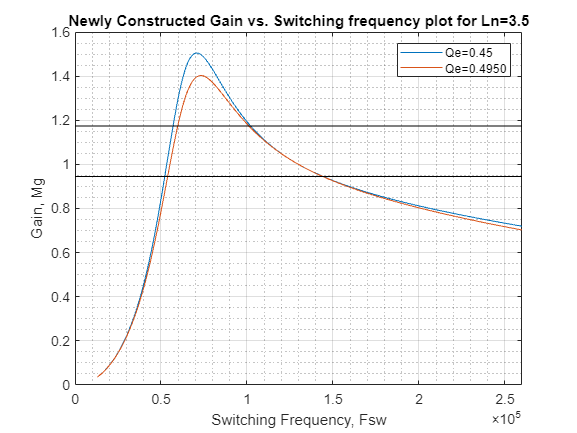


% ----
% Constructing gain vs. Switching frequency
Qe_calculated_in_step6=0.45;
Qe_overload_calculated_in_step6 = 0.4950;
selected_Ln = 3.5;

abs_Mgn = [];
plot_fswn = (0.1*130e3):100:((10*130e3));
for fswn = 0.1*130e3:100:10*130e3
    Mgn = (3.5*(fswn/130e3)^2)/( ( (3.5+1)*(fswn/130e3)^2 -1 ) + i*( ((fswn/130e3)^2-1)*(fswn/130e3)*Qe_calculated_in_step6*3.5) );
    abs_Mgn(end+1) = abs(Mgn);
end

abs_Mgm = [];
plot_fswm = (0.1*130e3):100:((10*130e3));
for fswm = 0.1*130e3:100:10*130e3
    Mgm = (3.5*(fswm/130e3)^2)/( ( (3.5+1)*(fswm/130e3)^2 -1 ) + i*( ((fswm/130e3)^2-1)*(fswm/130e3)*Qe_overload_calculated_in_step6*3.5) );
    abs_Mgm(end+1) = abs(Mgm);
end

plot(plot_fswn,abs_Mgn,plot_fswm,abs_Mgm)
title('Newly Constructed Gain vs. Switching frequency plot for Ln=3.5')
ylabel('Gain, Mg')
xlabel('Switching Frequency, Fsw')
hold on
line([0,2*fo],[Mg_max,Mg_max],'Color','black')
line([0,2*fo],[Mg_min,Mg_min],'Color','black')
%plot()
%plot()
grid on
grid minor
hold off
xlim([0 (2*130e3)])
legend({'Qe=0.45','Qe=0.4950'})


% fn_min
fsw_min = 1.01219e5;
fsw_max = 1.44307e5;

%%- Step 7
 % primary side RMS load current
Ioe_overload = (pi*I_op*1.1)/(2*sqrt(2)*n)

Ioe_overload = 2.2214

 % RMS magnetizing current
Im = (0.901*n*V_op)/(2*pi*fsw_min*Lm)

Im = 1.6481

 % resonanat ckt current or transformsers primary winding current
Ir = sqrt((Im^2)+(Ioe_overload^2))

Ir = 2.7660


%%- Step 8 
 % total secondary side RMS load current
Ioe_s = n * Ioe_overload

Ioe_s = 24.4359

 % current in each winding of a centre tapped transformer
Isw = (sqrt(2)*Ioe_s)/2

Isw = 17.2788

 % half wave avg current
Isav = (sqrt(2)*Ioe_s)/pi

Isav = 11.0000


%%- Step 9 
 % Consult and select an appropriate Transformer
 % selecting transformer
 % n=11
primary_terminal_voltage = 450;
primary_rated_current = 3; % in Ampere
I_wp = 3; % primary winding rated current
secondary_terminal_voltage = 36;
I_ws = Isw;
freq_no_load =  fsw_max;
freq_full_load = fsw_min;

%%- Step 10
 % In the calculation above Lr ~ 43 uH so selecting round figure
Lr = 45e-6; % in Henry
I_lr = 3; % in Ampere
V_lr = 2*pi*Lr*fsw_min*Ir

V_lr = 79.1609

 % selecting higher voltage rating
V_lr = 100 % in volts 

V_lr = 100

 % selecting frequency range from fsw_min to fsw_max

%%- Step 11
 % As frequency increases voltage of a capacitor must be derated
 % this can be done by observing the AC_voltage vs. Frequency
I_cr = 3;
V_cr = I_wp/(2*pi*fsw_min*Cr) % here I_wp is the rated current

V_cr = 136.0444


Vcr_rms = sqrt((Vin_high)^2+(V_cr)^2)

Vcr_rms = 417.7716

Vcr_peak = Vin_high/2 + (sqrt(2)*V_cr) 

Vcr_peak = 389.8958


%%- Step 12
 % The MOSFETs will have to bear Vin_high voltage across
 % Drain to source Terminal
V_Q1_peak = Vin_high

V_Q1_peak = 395

V_Q2_peak = Vin_high

V_Q2_peak = 395

 
 % the rated current will be Ir
I_Q1_rms = Ir

I_Q1_rms = 2.7660

I_Q2_rms = Ir

I_Q2_rms = 2.7660


%%- Step 13
 % for ZVS we need sufficient inductive energy and dead time
 % We need the Cds of the MOSFET, So get MOSFETs with appropriate
 % breakdown voltage and read their datasheet to find Cds

 % considering a typical 500V MOSFET
C_eq = 200e-12;
 % Im-min is the worst case
Im_min = (0.901*n*V_op)/(2*pi*fsw_max*Lm)

Im_min = 1.1560

 % Now verifying equations for inductive energy and dead time
Inductive_energy = 0.5*(Lm+Lr)*(sqrt(2)*Im_min)^2

Inductive_energy = 2.6230e-04

Capacitive_energy = C_eq*(Vin_high^2)

Capacitive_energy = 3.1205e-05


if Inductive_energy > Capacitive_energy
    disp("Conditions met")
else
    disp("Conditions not met")
end

Conditions met



t_dead_calc = 16*C_eq*fsw_max*Lm

t_dead_calc = 6.9865e-08

 % t_dead must be greater than what is calculated above
 % manually enter dead time value below
t_dead = 80e-9

t_dead = 8.0000e-08


%%- Step 14
 % Diodes need to meet the voltage requirement
 % to be safer select diodes with V_DB greater than calculated below
V_DB = (Vin_high*2)/(2*n)

V_DB = 35.9091

 % current rating for the diode is
I_sav = (sqrt(2)*Ioe_s)/(pi)

I_sav = 11.0000


%%- Step 15
 % rectifiers full wave output current
I_rect = (pi*I_op)/(2*sqrt(2))

I_rect = 22.2144

 % The RMS current for output capacitor
I_co = 0.482*I_op % complete formula - sqrt(((pi*I_op)/(2*sqrt(2)))^2-(I_op)^2)

I_co = 9.6400


 % the maximum ESR for our ripple voltage requirement can be calculated
 % Our requirement was 100mV of ripple
ESR_max = (0.1)/((pi/2)*(I_op)) % (0.100)/(((pi*I_op)/(4))*(2))

ESR_max = 0.0032

 % ESR must be less than the value calculated above

%%- Step 16 Bench testing